# **TDSÑ: Práctica 4**

Antes de comenzar ejecute el siguiente código para borrar las variables del espacio de trabajo, añadir el *toolbox* del laboratorio, establecer un tamaño de gráfica por defecto y eliminar algunos avisos del editor.

clear, subplot
disp(matlab.addons.install("Laboratorio TDSÑ.mltbx"))

           Name           Version    Enabled                  Identifier              
    __________________    _______    _______    ______________________________________

    "Laboratorio TDSÑ"     "1.7"      true      "f0cd2efa-daf1-4684-90dc-b476e9c0e6d9"



set(groot, 'DefaultFigurePosition', [0, 0, 500, 300])
%#ok<*NASGU>
%#ok<*ASGLU>

## **AVISO**

**Para poder ejecutar el código de esta práctica necesita tener instalada la siguiente caja de herramientas de MATLAB:**

- ***Signal Processing Toolbox***

El siguiente código comprueba si está instalada.

check_toolboxes("SG", 'es')

Correcto.


## **Instrucciones**

- *Escriba las direcciones de los correo-e suya y de su pareja en las variables *`alumno_1`* y *`alumno_2`* y ejecute la sección.*

- *La práctica incluye varias tareas que debe contestar en este mismo archivo en las zonas marcadas desde *`% SU CÓDIGO AQUÍ`* hasta *`% --------------.`

- *No cambie las llamadas a la función *`check_task`.

- *Cuando termine las tareas guarde este archivo y súbalo a la carpeta de entrega de Moodle. ****No cambie el nombre ni el tipo de archivo.***

alumno_1 = 'ignacio.aguirrec@alumnos.upm.es'; 
alumno_2 = 'ines.valdivielso@alumnos.upm.es';
check_task(400, 'es');

>>>>> [4:0:0] Correcto.


## Introducción

En la vida real la DFT se calcula con el algoritmo FFT. En la primera parte de esta práctica se estudia cómo utilizar las funciones [`fft`](matlab: doc fft) y [`fftshift`](matlab: doc fftshift) que proporciona MATLAB. En la segunda y tercera partes se abordan los rudimentos del análisis espectral, cuyo objetivo es identificar la composición frecuencial de un determinado espectro.

## 1. La DFT

### 1.1. Cálculo

La Transformada Rápida de Fourier (*Fast Fourier Transform, *FFT) es un algoritmo para calcular la DFT de forma rápida. MATLAB dispone de la función [`fft`](matlab: doc fft) que calcula y devuelve un vector con la DFT del vector de entrada.

El archivo `xlab4.mat` contiene las muestras de la señal continua compleja


$$x(t) = 2\cos(2\pi 15t)+0.5\,{\rm e}^{{\rm -j} 2\pi 40t}$$


Está formada por dos componentes: un coseno de frecuencia $f_0 = 15\,{\rm Hz}$ y una exponencial compleja de frecuencia $f_1 = -40\,{\rm Hz}$. Las muestras se han tomado con frecuencia de muestreo  $f_s = 100\,{\rm Hz}$ en el intervalo $0\le t \le 1\,\mathrm{s}$ para obtener la señal discreta $x[n]$.


load("xlab4.mat", "x", "fs")

La función [`fft`](matlab: doc fft) calcula y devuelve la DFT de la señal de entrada

X = fft(x);

Por defecto, el número de puntos de la DFT es igual a la longitud de la señal.

Para calcular una DFT de orden $N$ distinto de la longitud de la señal el valor se pasa como segundo argumento de la función [`fft`](matlab: doc fft)

N = 100;
X = fft(x, N);

Es habitual usar órdenes de la DFT que sean potencias de 2 porque permiten una mejor optimización de la correspondiente FFT. En MATLAB existe la función [`nextpow2`](matlab: nextpow2) para calcular el exponente de la siguiente potencia de 2 de un número. Aplicado a la longitud de la señal resulta

L = length(x);
N = pow2(nextpow2(L))

N = 64

X = fft(x, N);

#### Tarea 4.1.1

Sea $y[n]=\cos\left(\frac{\pi}{4} n\right)+0.25\sin\left(\frac{7\pi}{8} n\right)$ en el intervalo $0\le n \lt 256$. Calcule la DFT de $N=1024$ puntos de $y[n]$ y asigne su módulo a la variable `mY`.

clear n y mY N
% SU CÓDIGO AQUÍ
n = (0:255)'; % rango de n (0 a 255)
y = cos(pi/4*n) + 0.25*sin(7/8*pi*n); 
N = 1024; % Número de puntos de la DFT
Y = fft(y, N); % Calculamos la DFT de x[n]
mY = abs(Y); % Asignamos el módulo de la DFT a la variable mY
% --------------
check_task(411, 'es')

>>>>> [4:1:1] Correcto.


### **1.2. **Representación

La DFT calcula el contenido frecuencial de una señal en el intervalo de frecuencias discretas $0\le\omega\lt 2\pi$, en concreto en las frecuencias $\omega_k = \frac{2\pi k}{N},\,k=0,\dots,N-1$. El resultado $X[k]$ es una secuencia compleja de la cual se desea visualizar su magnitud $\left|X[k]\right|$.

Hay varias formas de representar el módulo de la DFT. Atendiendo a la amplitud: en unidades lineales, decibelios o potencia. Atendiendo a la variable independiente: en índices, frecuencia discreta o frecuencia continua relacionada con una determinada frecuencia de muestreo.

Para representar correctamente una FFT hay que calcular el vector de frecuencias del eje de abscisas. Hay varias formas de hacerlo:

1. **Vector de índices **$k$: la DFT es una secuencia, por lo que puede representarse como tal. Representación de la magnitud en unidades lineales:

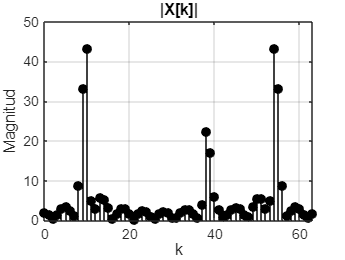

N = length(X);
k = (0:N-1)';
mX = abs(X);
stem(k, mX, "k", "filled"), grid on
xlim([0, N-1]), xlabel("k"), title("|X[k]|")
ylabel("Magnitud")

La magnitud o módulo en unidades lineales se calcula con la función [`abs`](matlab: doc abs).

2. **Vector de frecuencias discretas** $\omega_k$. Representación de la magnitud en decibelios:

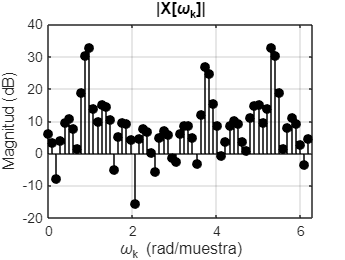

N = length(X);
k = (0:N-1)';
wk = 2*pi*k/N;
mX = abs(X);
stem(wk, 20*log10(mX), "k", "filled"), grid on
xlim([0, 2*pi]), xlabel("\omega_k (rad/muestra)"), title("|X[\omega_{k}]|")
ylabel("Magnitud (dB)")

Para pasar la magnitud a decibelios se puede usar [`mag2db`](matlab: doc mag2db) o usar la expresión `20*log10`.

3. **Vector de frecuencias continuas **$f_k$. Esta representación es adecuada para relacionar las frecuencias discretas con las frecuencias continuas. Representación de la potencia en decibelios:

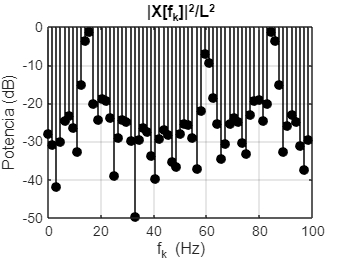

N = length(X);
k = (0:N-1)';
fk = k*fs/N;
pX = abs(X).^2/L^2;
stem(fk, pow2db(pX), "k", "filled"), grid on
xlim([0, fs]), xlabel("f_k (Hz)"), title("|X[f_{k}]|^{2}/L^2")
ylabel("Potencia (dB)")

Para el cálculo en decibelios de la potencia se puede usar [`pow2db`](matlab: doc pow2db) o usar la expresión `10*log10`.

Esta representación no es estrictamente correcta porque el rango de frecuencias $\frac{fs}{2}\lt f_k\lt f_s$ son, en puridad, frecuencias negativas. Más adelante se aborda este problema.

Cuando el número de puntos de la DFT es relativamente grande ($N \ge\, \sim128$) es preferible dibujar con [`plot`](matlab: doc plot) en lugar de [`stem`](matlab: doc stem).

#### Tarea 4.1.2

Sea la señal


$$s(t) = \cos(2\pi f_0t)+0.5\sin(2\pi 3f_0t)$$


con $f_0=60\,\mathrm{Hz}$ muestreada a frecuencia $f_s=1\,\mathrm{kHz}$ en el intervalo $0 \le t \lt 1\,\mathrm{s}$.

Calcule la DFT de $N=1000$ puntos de $s(t)$ y represente (usando la función [`plot`](matlab: doc plot)) su potencia en dB en función del índice $k$.

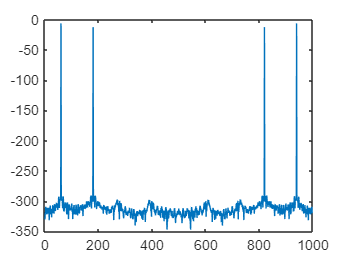

clear n fo t s k N
% SU CÓDIGO AQUÍ
fo = 60; 
fs = 1e3; 
%t = (0:1/fs:1-1/fs)'; % Intervalo de tiempo muestreado a fs
t = (0:fs-1)'/fs;

s = cos(2*pi*fo*t) + 0.5*sin(2*pi*3*fo*t); 

N = 1000; 
S = fft(s, N); 
L = length(s);
pS = abs(S).^2/L^2;
%pS = 20*log10(S);
%pS = mag2db(S);

k = (0:N-1)';
fk = k*fs/N;

%hold off;
plot(fk, pow2db(pS))

%plot(fk, abs(pS))
% --------------
check_task(412, 'es')

>>>>> [4:1:2] Correcto.


#### Tarea 4.1.3

Para la misma señal $s(t)$ de la tarea 4.1.2 calcule la DFT de $N=1024$ puntos y represente (usando la función [`plot`](matlab: doc plot)) su magnitud en unidades lineales en función de la frecuencia discreta $\omega_k$.

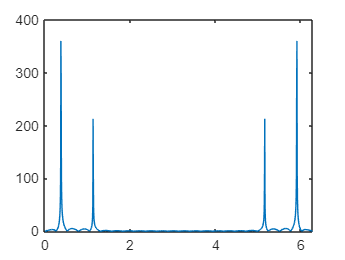

clear wk N
% SU CÓDIGO AQUÍ
fo = 60; 
fs = 1e3; 
t = (0:1/fs:1-1/fs)'; % Intervalo de tiempo muestreado a fs

s = cos(2*pi*fo*t) + 0.5*sin(2*pi*3*fo*t); 

N = 1024; 
S = fft(s, N); 

k = (0:N-1)'; % Índices
wk = 2*pi*k/N; % Frecuencia discreta en radianes

% Representación de la magnitud en unidades lineales
plot(wk, abs(S)) 

% --------------
check_task(413, 'es')

>>>>> [4:1:3] Correcto.


#### Tarea 4.1.4

Para la misma señal $s(t)$ de la tarea 4.1.2 calcule la DFT de $N=1000$ puntos y represente (usando la función [`plot`](matlab: doc plot)) su magnitud en dB en función de la frecuencia continua $f_k$.

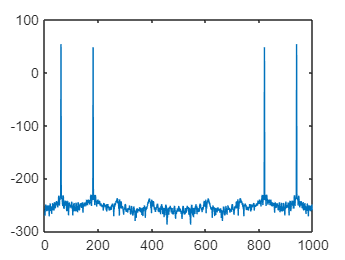

clear fk N
% SU CÓDIGO AQUÍ
fo = 60; 
fs = 1e3; 
%t = (0:1/fs:1-1/fs)'; 
t = (0:fs-1)'/fs;
s = cos(2*pi*fo*t) + 0.5*sin(2*pi*3*fo*t); 
N = 1e3; 

S = fft(s, N);
%L = length(s);
mS_dB = 20*log10(abs(S));
%pS = abs(S).^2 / length(s)^2; 

k = (0:N-1)'; 
fk = k*fs/N; 

plot(fk, mS_dB)

% --------------
check_task(414, 'es')

>>>>> [4:1:4] Correcto.


### **1.3. Centrado**

Si se desea representar la DFT en el intervalo $[-\pi,\pi)$, es decir, centrada en la frecuencia 0, se debe usar la función [`fftshift`](matlab: doc fftshift), que reordena el vector generado por la FFT haciendo un desplazamiento circular.

load("xlab4.mat", "x", "fs");
X = fft(x);
X_c = fftshift(X);

También hay que cambiar los valores de frecuencia para que coincidan. Para el caso habitual en el que $N$ es par basta con restar $\pi$ o $f_s/2$ a los valores de frecuencia discreta o continua, respectivamente.

N = length(X);
k = (0:N-1)';
fk = k*fs/N;
fk_c = fk - fs/2;

La representación de la magnitud centrada en frecuencias continuas y en unidades lineales se haría con

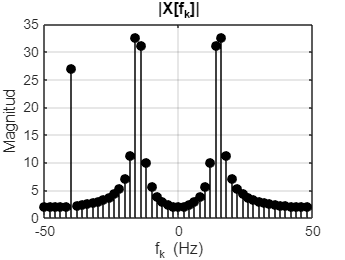

stem(fk_c, abs(X_c), "k", "filled"), grid on
xlim([-fs/2, fs/2]), xlabel("f_k (Hz)"), title("|X[f_{k}]|")
ylabel("Magnitud")

Ahora sí, esta representación es correcta.

Cuando una señal es real su espectro es simétrico respecto a 0 por lo que basta con representar las frecuencias positivas, es decir la primera mitad de la FFT. Por ejemplo, con la parte real de $x[n]$:

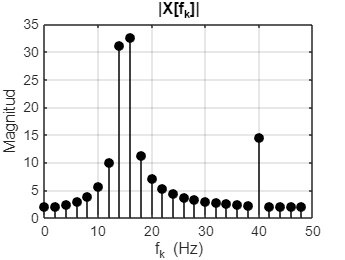

z = real(x);
Z = fft(z, N);
fk_half = fk(1:N/2);
Z_half = Z(1:N/2);
stem(fk_half, abs(Z_half), "k", "filled"), grid on
xlim([0, fs/2]), xlabel("f_k (Hz)"), title("|X[f_{k}]|")
ylabel("Magnitud")

#### Tarea 4.1.5

Para la misma señal $s(t)$ de la tarea 4.1.2 calcule la DFT de $N=1024$ puntos y represente (usando la función [`plot`](matlab: doc plot)) su magnitud en dB en función de las frecuencias continuas positivas $f_k$.

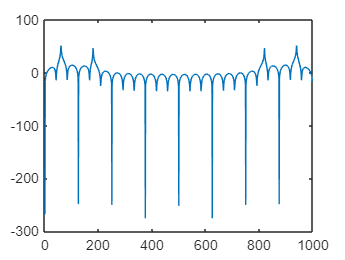

clear fk N
% SU CÓDIGO AQUÍ
fo = 60; 
fs = 1e3; 
L = fs;
%t = (0:1/fs:1-1/fs)'; 
t = (0:fs-1)'/fs;
s = cos(2*pi*fo*t) + 0.5*sin(2*pi*3*fo*t); 

N = 1024; 
S = fft(s, N); 
%mS_dB = 20*log10(abs(S));
pS = mag2db(abs(S));
%pS = abs(S).^2 / length(s)^2; 

k = (0:N-1)'; 
fk = k*fs/N; 

%plot(fk, pow2db(pS)) 
plot(fk(1:N/2), pS(1:N/2))


% --------------
check_task(415, 'es')

>>>>> [4:1:5] Error: Los valores del eje de abscisas (x) no son correctos.


## 2. Análisis espectral de señales deterministas de banda estrecha

El objetivo del análisis espectral con este tipo de señales es encontrar con precisión el contenido frecuencial de las mismas. Si la señal está formada por sinusoides y/o exponenciales complejas el espectro muestra picos cuyas posiciones y amplitudes determinan las componentes de la señal.

### 2.1. Localización de picos

MATLAB dispone de la función [`findpeaks`](matlab: doc findpeaks) para localizar picos en un vector. La sintaxis más adecuada es la siguiente

`[pk, loc]` `=` `findpeaks``(x, f, NPeaks=n``, SortStr="descend"``)`

donde `x` son los valores de la señal, `f` los valores de la variable independiente y `n` el número de picos a buscar. Los valores devueltos son `pk` con la amplitud de los picos y `loc` con su "posición", es decir, el valor de la variable independiente en el que ocurren. Si no se indica ningún parámetro opcional la función devuelve los primeros picos localizados. Para devolver los picos más prominentes hay que clasificarlos de forma descendente con `SortStr="descend"`.

Por ejemplo, para localizar los 3 picos del espectro de potencia de la señal $x[n]$ en las frecuencias continuas centradas:

load("xlab4.mat", "L", "x", "fs", "f0")
N = L;
fk_c = fs*(0:N-1)'/N - fs/2;
X_c = fftshift(fft(x, N));
pX_c = mag2db(abs(X_c));
[pk, loc] = findpeaks(pX_c, fk_c, NPeaks=3, SortStr="descend")

pk =    30.2541
   30.2541
   28.6315


loc =    -16
    16
   -40


Como comprobación se puede pintar el espectro y colorear los resultados

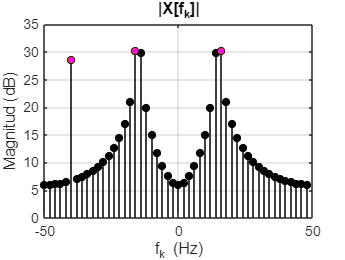

stem(fk_c, pX_c, "k", "filled", MarkerSize=5), grid on
xlim([-fs/2, fs/2]), xlabel("f_k (Hz)"), title("|X[f_{k}]|")
ylabel("Magnitud (dB)")
hold on
plot(loc, pk, "o", MarkerSize=4, MarkerFaceColor="m")
hold off

#### Tarea 4.2.1

En el archivo `xlab4.mat` se encuentra una señal `x`. Calcule la amplitud y frecuencia discreta de los 2 picos más prominentes de la magnitud en unidades lineales del espectro de frecuencias discretas positivas de la DFT de $N=64$ puntos de $z[n]=\Re\{x[n]\}$. Asigne el resultado a las variables `pk_z` y `loc_z`.

clear z N pk_z loc_z
load("xlab4.mat", "x");
% SU CÓDIGO AQUÍ
N = 64; 
k = (0:N-1)'; % Índices
wk = 2*pi*k/N; % Frecuencia discreta en radianes
z = real(x);
Z = fft(z, N);
pZ = abs(Z);
[pk_z, loc_z] = findpeaks(pZ(1:N/2), wk(1:N/2), NPeaks=2, SortStr="descend")

pk_z =    43.2371
   11.3981


loc_z =     0.9817
    2.5525



% --------------
check_task(421, 'es')

>>>>> [4:2:1] Correcto.


Las frecuencias obtenidas con [`findpeaks`](matlab: doc findpeaks) no son siempre precisas. La frecuencia del coseno es $f_0=15\,\mathrm{Hz}$ pero el resultado `loc(2)` tiene una diferencia de $1\,\mathrm{Hz}$ equivalente a un error relativo del $6.67\%$.

loc(2)

ans = 16

e = 100*abs(loc(2) - f0)/f0

e = 6.6667

Observe en la gráfica que no hay muchos marcadores cerca del pico. No es posible encontrar el valor correcto de frecuencia si no hay un valor de la DFT exactamente en la frecuencia del pico.

Un remedio sencillo es hacer una interpolación parabólica usando el valor del pico y sus adyacentes y calcular el valor máximo de la parabóla resultante.

idx = find(fk_c==loc(2)) + (-1:1);
p = polyfit(fk_c(idx), pX_c(idx), 2);

f = -p(2)/(2*p(1))

f = NaN

e = 100*abs(f - f0)/f0

e = NaN

El error se reduce al $0.6\%$.

Pero si se dispone de la señal, la mejor alternativa es aumentar el orden de la DFT, lo que hace que los valores de frecuencia estén más próximos. Esta técnica se conoce como *relleno con ceros*.

load("xlab4.mat", "x", "fs", "f0")
N = 8192;
mX_c = fftshift(abs(fft(x, N)));
fk_c = fs*(0:N-1)'/N - fs/2;
[pk, loc] = findpeaks(mX_c, fk_c, NPeaks=3, SortStr="descend")

pk =    50.5187
   50.5156
   27.0130


loc =   -15.0269
   15.0269
  -40.0024


e = 100*abs(loc(2) - f0)/f0

e = 0.1790

En este caso el error se reduce al $0.2\%$.

In this case the error is reduced to $0.2\%$.

Para facilitar el cálculo correcto de frecuencias se debe usar, en general, un orden $N$ "grande" pero este valor también afecta al tiempo de cálculo de la FFT.

### 2.2. Ventanas

Las señales de duración infinita, como sinusoides y exponenciales complejas, no admiten una transformada de duración finita como la DFT. Para ver el espectro de estas señales mediante una DFT es preciso limitar su duración multiplicándolas por una ventana $w[n]$ de duración finita $L$. Esta operación afecta al cálculo del espectro ya que la multiplicación en el dominio temporal se convierte en una convolución (periódica) en el dominio transformado. El espectro que puede observarse $X_{w}(\omega)$ es el de la señal $x[n]$ visto a través de la ventana $w[n]$.

MATLAB dispone de multitud de funciones para calcular ventanas: rectangular ([`rectwin`](matlab: doc rectwin)), triangular ([`triang`](matlab: doc triang)), Hamming ([`hamming`](matlab: doc hamming)),  Kaiser ([`kaiser`](matlab: doc kaiser)) y muchas otras. También dispone de las herramienta [`wvtool`](matlab: doc wvtool) para visualizar ventanas y [`windowDesigner`](matlab: doc windowDesigner) para compararlas. Por ejemplo, para visualizar una ventana de Hamming de 100 puntos:

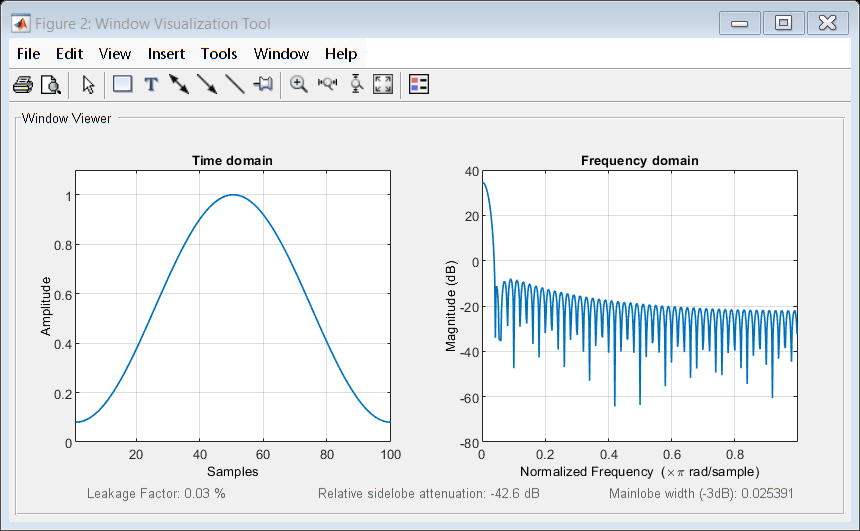

wvtool(hamming(100))

En el menú *View > Analysis Parameters* de la herramienta se puede elegir la representación espectral de la ventana.

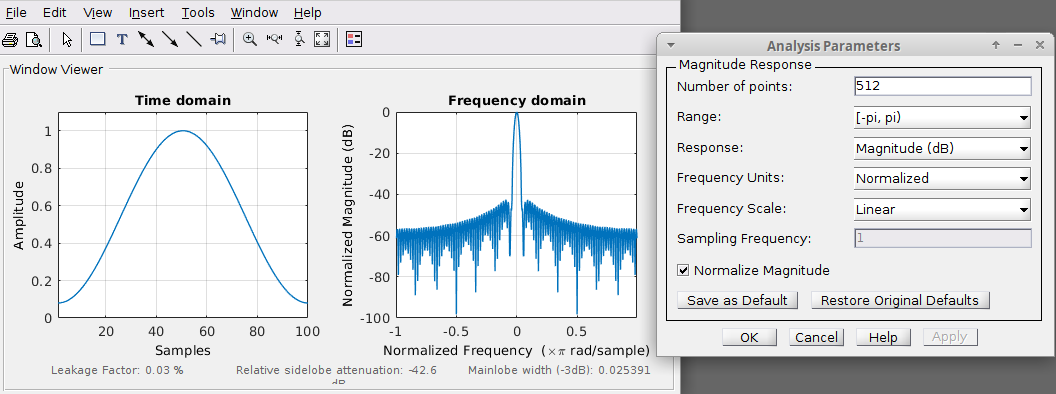

Para aplicar una ventana de longitud $L$ a una señal hay que multiplicar un segmento de $L$ muestras de la señal por los valores de la ventana. Por ejemplo, para aplicar una ventana de Hamming de longitud $L=20$ a la señal $s[n] = \cos\left(\frac{\pi}{4}n\right)$ a partir de $n_0=10$, suponiendo que se disponen de $M=100$ muestras de $s[n]$ en el intervalo $0 \le n \le M-1$:

M = 100;
n = (0:M-1)';
L = 20;
s = cos(pi*n/4);                %  señal x[n] en el intervalo 0 <= n <= M-1
n0 = 10;
s0 = s(n0+(1:L));               %  segmento de x[n]
s0_hamming = s0.*hamming(L);    %  segmento enventanado

#### Tarea 4.2.2

Aplique una ventana gaussiana ([`gausswin`](matlab: doc gausswin)) al segmento de longitud $L=64$ de la señal $s[n] = \cos\left(\frac{\pi}{4}n\right)$ a partir de $n_0=32$, suponiendo que se disponen de $M=100$ muestras de $s[n]$ en el intervalo $0 \le n \le M-1$. Asigne el resultado a la variable `s0_gauss`.

% SU CÓDIGO AQUÍ
L = 64;
M = 100;
n0 = 32;
n = (0:M-1)';

s = cos(n*pi/4);
s0 = s(n0+(1:L));

s0_gauss = s0.*gausswin(L);
% --------------
check_task(422, 'es');

>>>>> [4:2:2] Correcto.


La forma de una ventana determina el ancho del lóbulo principal y la altura de los lóbulos laterales de su transformada de Fourier. En general, se desea lóbulo principal estrecho y lóbulos laterales pequeños, pero no es posible optimizar ambas propiedades a la vez.

Al aplicar una ventana sus propiedades se reflejan en dos propiedades: resolución frecuencial y fugas espectrales. Un lóbulo principal estrecho proporciona una buena resolución de frecuencia. Con lóbulos laterales pequeños se producen fugas espectrales reducidas.

El siguiente código compara los espectros normalizados de tres ventanas de uso frecuente: rectangular, Hamming y Blackman-Harris.

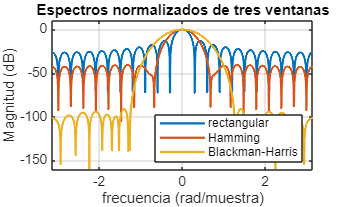

L = 21; N = 4096;
w = [rectwin(L), hamming(L), blackmanharris(L)];
W = 20*log10(abs(fftshift(fft(w, N), 1)));
wk = 2*pi*(0:N-1)'/N;
plot(wk-pi, W-max(W), LineWidth=1.5);
title("Espectros normalizados de tres ventanas"), grid on
xlabel("frecuencia (rad/muestra)"), ylabel("Magnitud (dB)")
xlim([-pi, pi]), ylim([-160, 10])
legend("rectangular", "Hamming", "Blackman-Harris", Location="southeast")

Observe cómo la reducción de la magnitud de los lóbulos laterales provoca el aumento de la anchura del lóbulo principal.

#### Tarea 4.2.3

La ventana de Kaiser (función [`kaiser`](matlab: doc kaiser)) depende de un parámetro $\beta$ que permite ajustar sus propiedades. Con $\beta=0$ y $\beta=4.86$ la ventana de Kaiser tiene unas propiedades muy similares a la rectangular y a la de Hamming, respectivamente. Seleccione un valor de $\beta$ y asígnelo a la variable `beta` del siguiente código para que la tercera ventana de Kaiser se asemeje a la ventana de Blackman-Harris.

clear beta
% SU CÓDIGO AQUÍ
beta = 12;
% --------------
L = 21; N = 4096;
w = [kaiser(L, 0), kaiser(L, 4.86), kaiser(L, beta)];
W = 20*log10(abs(fftshift(fft(w, N), 1)));
wk = 2*pi*(0:N-1)'/N;
plot(wk-pi, W-max(W), LineWidth=1.5);
title("Espectros normalizados de tres ventanas"), grid on
xlabel("frecuencia (rad/muestra)"), ylabel("Magnitud (dB)")
xlim([-pi, pi]), ylim([-160, 10])
legend("Kaiser(0)", "Kaiser(4.86)", "Kaiser("+beta+")", Location="southeast")

check_task(423, 'es')

>>>>> [4:2:3] Correcto.


La ventana más adecuada para resolver componentes con frecuencias muy próximas es la rectangular porque ofrece la menor anchura del lóbulo principal. La ventana más adecuada para ver componentes con gran diferencia de amplitud es la que tenga unos lóbulos laterales más pequeños para minimizar las fugas espectrales. En este caso la de Blackman-Harris.

### **2.4. Ejemplos de análisis**

En las siguientes tareas se analizan dos señales con componentes sinusoidales y exponenciales complejas. En ambas tareas se muestra la magnitud en decibelios del espectro de la señal. Los triángulos del gráfico marcan los picos encontrados con la función [`findpeaks`](matlab: doc findpeaks).


load("yzlab4.mat")

#### **Tarea 4.2.4**

Modifique el valor `beta` de la ventana de Kaiser con el control deslizante hasta que los marcadores se sitúen en los picos de señal.

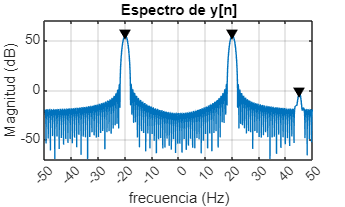

N = 4096;
beta = 6.75;
w = kaiser(L, beta);
Y = 20*log10(fftshift(abs(fft(y.*w, N))));
fk = fs*(0:N-1)'/N - fs/2;
plot(fk, Y), grid on, title("Espectro de y[n]")
xlabel("frecuencia (Hz)"), ylabel("Magnitud (dB)")
[pk, loc] = findpeaks(Y, fk, NPeaks=3, SortStr="descend", MinPeakWidth=1);
ylim([-70, 70]), xlim([-50, 50]), xticks(-50:10:50)
hold on, plot(loc, pk+3, 'v', MarkerFaceColor="k", MarkerEdgeColor="k"), hold off

check_task(424)

>>>>> [4:2:4] Correcto.


Una vez localizados correctamente los picos de la señal se pueden determinar las frecuencias y amplitudes de las componentes. Para hacer este cálculo se necesita compensar la magnitud del pico con el valor de la transformada de la ventana en continua. Este valor se calcula fácilmente sumando los valores de la ventana en el dominio del tiempo:

W0 = sum(w);

Con este dato se pueden calcular la amplitud y frecuencia de la sinusoide:

f_sin = loc(2)

f_sin = 19.9951

A_sin = (2/W0)*10.^(pk(2)/20)

A_sin = 20.0016

Aí como la amplitud y frecuencia de la exponencial compleja:

f_exp = loc(3)

f_exp = 45.0439

A_exp = (1/W0)*10.^(pk(3)/20)

A_exp = 0.0119

El valor calculado de la amplitud de la exponencial mejorará cuando su pico sobresalga notablemente de los lóbulos laterales de los picos del coseno; es decir, para valores grandes de $\beta$.

#### **Tarea 4.2.5**

Modifique el valor `beta` de la ventana de Kaiser con el control deslizante hasta que los marcadores se sitúen en los picos de señal.

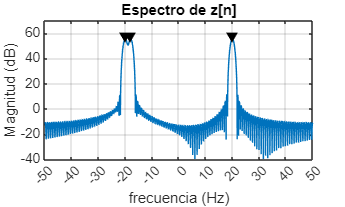

N = 4096;
beta = 6;
w = kaiser(L, beta);
Z = 20*log10(fftshift(abs(fft(z.*w, N))));
fk = fs*(0:N-1)'/N - fs/2;
plot(fk, Z), grid on, title("Espectro de z[n]")
xlabel("frecuencia (Hz)"), ylabel("Magnitud (dB)")
[pk, loc] = findpeaks(Z, fk, NPeaks=3, SortStr="descend", MinPeakWidth=1);
ylim([-40, 70]), xlim([-50, 50]), xticks(-50:10:50)
hold on, plot(loc, pk+3, 'v', MarkerFaceColor="k", MarkerEdgeColor="k"), hold off

check_task(425)

>>>>> [4:2:5] Correcto.


**Tarea 4.2.6**

Calcule las frecuencias y amplitudes de las componentes. Asígnelas a las variables `f_sin` y `A_sin` (sinusoide) y `f_exp` y `A_exp` (exponencial compleja).

Nota: consulte los valores de la variable `loc`. El orden de los picos puede variar.

clear f_sin A_sin f_exp A_exp
% SU CÓDIGO AQUÍ
W0 = sum(w);
f_sin = loc(2)

f_sin = 19.9951

A_sin = (2/W0)*10.^(pk(2)/20)

A_sin = 1.4870


f_exp = loc(3);
A_exp = (1/W0)*10.^(pk(3)/20)

A_exp = 0.7433


% --------------
check_task(426, 'es')

>>>>> [4:2:6] Error: La variable <A_sin> no tiene valor(es) correcto(s).
El primer valor incorrecto es: A_sin(1).


## 3. Análisis espectral de señales aleatorias

En muchas situaciones las señales aleatorias son de banda ancha y no interesa detectar o medir picos espectrales sino analizar cómo se distribuye la potencia de la señal en las distintas frecuencias. La herramienta más adecuada es la densidad espectral de potencia, DEP o PSD (*power spectral density*). Si una señal aleatoria es estacionaria y ergódica su DEP puede estimarse a partir de una realización suficientemente grande.

En este apartado se usa el análisis espectral para estimar el módulo de la respuesta en frecuencia de un filtro $\left|H(\omega)\right|$. Con este fin se hace uso de la expresión


$$S_{yy}(\omega)=\sigma^2\left|H(\omega)\right|^2$$


que determina la DEP de la salida $y[n]$ de un filtro LTI cuando a la entrada se pone ruido blanco con varianza $\sigma^2$.

Sea $H(z)$ el sistema que se pretende caracterizar. Se trata de un filtro IIR de 2º orden con las siguiente función de transferencia:


$$H(z)=0.06\frac{1+2z^{-1}+z^{-2}}{1-1.3z^{-1}+0.845z^{-2}}$$


En un escenario real esta función sería desconocida pero así se pueden comparar los resultados obtenidos con el correcto.

La DEP determinista del filtro puede calcularse fácilmente:

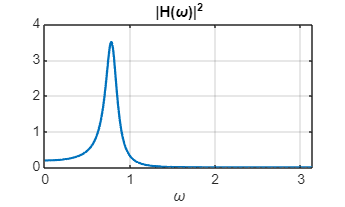

B = 0.06*[1, 2, 1];
A = [1, -1.3, 0.845];
[H, w] = freqz(B, A);
P_hh = abs(H).^2;
plot(w, P_hh, LineWidth=1.5), grid on
title("|H(\omega)|^2"), xlabel("\omega"), xlim([0, pi])

Como se puede observar se trata de un filtro paso bajo con una resonancia muy acusada cerca de la frecuencia de corte.

Para generar la señal de entrada $x[n]$ como una realización de ruido blanco gaussiano se usa la función [`randn`](matlab: doc randn). Por ejemplo, para generar $x[n]$ de longitud $L=512$ y varianza $\sigma^2=5$:

L = 512;
sigma = sqrt(5);
x = sigma*randn(L, 1);

La salida del filtro se calcula con la función [`filter`](matlab: doc filter)

y = filter(B, A, x);

Las primeras 100 muestras se descartan para eliminar la salida transitoria del filtro y así asegurar que la señal de salida $y[n]$ es estacionaria.

y = y(101:end);

### 3.1. Periodograma

Para estimar la DEP del proceso aleatorio se usa, en primer lugar, el periodograma, definido como


$$I(\omega)=\frac{1}{L}\left|X(\omega)\right|^2$$


#### Tarea 4.3.1

Genere una realización $z[n]$ de ruido blanco gaussiano de longitud $L=512$ y varianza $\sigma^2=10$ y asígnela a la variable `z`. Calule y dibuje su periodograma $I[k]$ en decibelios y con eje de frecuencias discretas usando una DFT de $N=1024$ puntos.

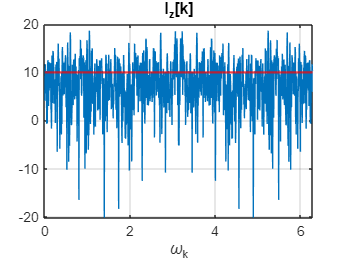

rng(0)    %  AVISO: no cambie esta línea de código
clear z I N
% SU CÓDIGO AQUÍ
L = 512;
sigma = sqrt(10);
z = sigma*randn(L, 1);
N = 1024;
   
Z = fft(z, N);
I = abs(Z).^2 / L;


I_dB = pow2db(I); 

k = (0:N-1)';
wk = 2*pi*k/N; 


plot(wk, I_dB)

% --------------
grid on, xlabel("\omega_k"), title("I_{z}[k]"), xlim([0, 2*pi])
yline(pow2db(sigma^2), "r", LineWidth=1.5)

check_task(431, 'es')

>>>>> [4:3:1] Correcto.


La DEP de un ruido blanco gaussiano, marcada con una línea roja en la gráfica, es una constante de valor $\sigma^2$. Sin embargo, el periodograma muestra algo muy distinto. Aparentemente, podría sospecharse que hay componentes de banda estrecha por los picos que muestra el espectro, pero esta suposición es errónea.

MATLAB dispone de la función [`periodogram`](matlab: doc periodogram) con la que puede calcularse tanto el peridograma normal como el periodograma modificado, que usa una ventana $w[n]$ no rectangular: $I(\omega)=\frac{1}{LU}\left|V(\omega)\right|^2$, donde $v[n]=x[n]w[n]$ y $U=\frac{1}{L}\sum_{n=0}^{L-1}|w[n]|^2$ es el factor que corrige el efecto de la ventana.

Sin argumentos de salida, la función dibuja el periodograma en decibelios

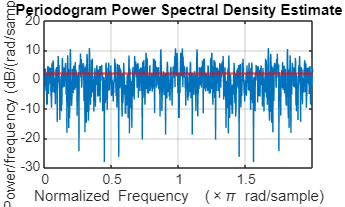

periodogram(z, rectwin(L), N, "twosided")
yline(pow2db(sigma^2/(2*pi)), "r", LineWidth=1.5)

Si se compara con la representación precedente se puede observar una diferencia de nivel debida al factor de escala $2\pi$ que la función aplica en el denominador de la constante de normalización.

El segundo parámetro de la función [`periodogram`](matlab: doc periodogram) es la ventana que se aplica para calcular el periodograma. El tercero es el número de puntos de la DFT. El último, `"twosided",` se ha usado para dibujar el espectro completo; si se omite, el espectro muestra únicamente las frecuencias positivas y se dobla el valor de las muestras espectrales (excepto para $\omega=0$ y $\omega=\pi$).

#### Tarea 4.3.2

Use la función [`periodogram`](matlab: doc periodogram) para dibujar el periodograma modificado de la señal $z[n]$ calculada en la tarea 4.3.1 usando una ventana de Kaiser con $\beta=10$. La longitud de la DFT debe ser $N=2048$.

rng(0)    %  AVISO: no cambie esta línea de código
% SU CÓDIGO AQUÍ
beta = 10;
N = 2048;
L = 512;
sigma = sqrt(10);
z = sigma*randn(L, 1);
Z = fft(z, N);

w_kaiser = kaiser(L, beta);
periodogram(z, w_kaiser, N);

% --------------
yline(pow2db(10/(2*pi)), "r", LineWidth=1.5);

check_task(432, 'es')

>>>>> [4:3:2] Correcto.


El periodograma modificado no mejora la estimación. Los efectos del enventanado son muy relevantes cuando se manipulan sinusoides pero son casi imperceptibles con el ruido blanco. Aún así, merece la pena ver cómo se aplica a la estimación de la respuesta del filtro

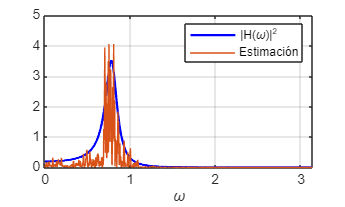

L0 = 2048 + 100;
x = randn(L0, 1);
y = filter(B, A, x);
y = y(101:end);
L = L0 - 100;
N = 2^nextpow2(L);
[H, w] = freqz(B, A, N/2);
P_hh = abs(H).^2;
plot(w, P_hh, "b", LineWidth=1.5)
[P, wp] = periodogram(y, kaiser(L, 10), N);
hold on, plot(wp, P), hold off
grid on, xlabel("\omega"), xlim([0, pi])
legend("|H(\omega)|^2", "Estimación"), 

PF = pi*[2*P(1); P(2:end-1)];
mse = mean(abs(PF-P_hh).^2)

mse = 0.9246

En el código se ha omitido la varianza del ruido porque es equivalente a usar $\sigma^2=1$. La penúltima línea ajusta la normalización para poder calcular con la última línea el error cuadrático medio (MSE, *mean square error*) de la aproximación.

Si ejecuta de nuevo este código observará que la estimación no es buena y que el error cuadrático medio no baja de $MSE \approx 0.2$.

La estimación tampoco mejora significativamente con ventanas más largas. La media se acercará al valor real pero con variaciones no decrecientes, porque el periodograma es un estimador asintóticamente insesgado pero no consistente.

### 3.2. Promediado de periodogramas

Para resolver el problema de la variabilidad es habitual usar los métodos de Bartlett o Welch que consisten en promediar los periodogramas de segmentos solapados de la señal bajo análisis. La única diferencia entre ambos es que el primero promedia periodogramas normales (con ventana rectangular) mientras que el segundo promedia periodogramas modificados (con cualquier otra ventana).

La función para aplicar cualquiera de estos métodos es [`pwelch`](matlab: doc pwelch) y requiere como tercer parámetro el número de muestras de solpamiento. Aplicado a una señal de ruido $x[n]$ de longitud $L=5120$ muestras en segmentos de $L_w=512$ muestras con solapamiento de la mitad del segmento y con ventana rectangular:

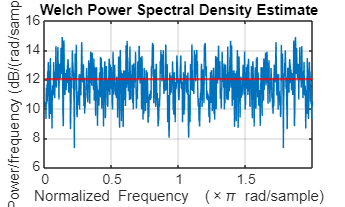

Lw = 512;
L = 5120;
sigma = 10;
x = sigma*randn(L, 1);
pwelch(x, rectwin(Lw), Lw/2, N, "twosided")
yline(pow2db(sigma^2/(2*pi)), "r", LineWidth=1.5)

Se aprecia que la varianza se ha reducido en un factor $K=20$ correspondiente al número de segmentos solapados.

En esta sección se muestra el resultado de aplicar el método de Bartlett con longitud de la señal variable y, por tanto, del número de segmentos promediados.

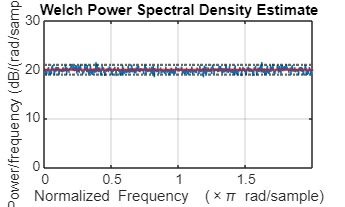

Lw = 512;
l = 15;
L = 2^l;
sigma = 25;
x = sigma*randn(L, 1);
pwelch(x, rectwin(Lw), Lw/2, N, "twosided")
yline(pow2db(sigma^2/(2*pi)), "r", LineWidth=1.5)
yline(pow2db(sigma^2/(2*pi))+1, ":", LineWidth=1.5)
yline(pow2db(sigma^2/(2*pi))-1, ":", LineWidth=1.5)
ylim([0, 30])

Observe cómo para $L\gt\approx2^{15}$ el error de la estimación está en el margen $\pm 1\,\mathrm{dB}$.

#### Tarea 4.3.3

Aplique el método de Bartlett al proceso de salida $y[n]$ del filtro que se desea caracterizar. El código debe:

- Generar una realización de de longitud $L$ de ruido blanco gaussiano con $\sigma^2=1$.

- Filtrar la señal de ruido con el filtro de coeficientes `B` y `A.`

- Calcular con la función [`pwelch`](matlab: doc pwelch) el promedio de los periodogramas en el intervalo $[0, \pi]$de la señal filtrada, usando una ventana rectangular de $L_w=2048$ muestras, con solapamiento de $L_w/2$ y número de puntos de la DFT $N=1024$. Asigne la salida de la función a la variable `PW`. Nota: la función devuelve $N/2 + 1$ muestras de la estimación; la última muestra no es necesaria y debe eliminarse para poder comparar con el resultado de la función [`freqz`](matlab: doc freqz). 

- Corregir la normalización de la función multiplicando por $2\pi$ el primer elemento y por $\pi$ los restantes.

- Calcular el error cuadrático medio de la estimación. Asigne el resultado a la variable `mse`.

Elija la longitud $L$ de modo que sea la menor potencia de que 2 que haga que el error cuadrático medio de la estimación sea menor que ${10}^{-3}$.

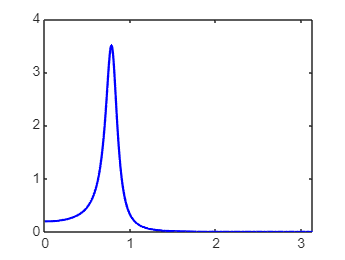

clear L mse
Lw = 2048;
N = 1024;
B = 0.06*[1, 2, 1];
A = [1, -1.3, 0.845];
[H, w] = freqz(B, A, N/2);
P_hh = abs(H).^2;
plot(w, P_hh, "b", LineWidth=1.5)
% SU CÓDIGO AQUÍ

L = 2^20;
sigma = 1;
y = sigma*randn(L,1);
y = y(100:end);
z = filter(B, A, y);
[PW, w] = pwelch(z, rectwin(Lw), Lw/2, N);
PF = pi*[2*PW(1); PW(2:end-1)];
mse = mean(abs(PF-P_hh).^2);

% --------------
hold on, plot(w, PW), hold off
grid on, xlabel("\omega"), xlim([0, pi])
legend("|H(\omega)|^2", "Estimación")

check_task(433, 'es')

>>>>> [4:3:3] Error: La variable <mse> no tiene valor(es) correcto(s).
El primer valor incorrecto es: mse(1).


A partir de la estimación de la DEP del filtro se puede generar un filtro FIR que lo aproxime:

He = [sqrt(PW); flip(sqrt(PW))]; % Espectro completo del filtro estimado
he = ifft(He, "symmetric");      % he[n] = DFT inversa, asegurando que es real
[He, w] = freqz(he, 1, N/2);
plot(w, [abs(H), abs(He)]), grid on
grid on, xlabel("\omega"), xlim([0, pi])
legend("|H(\omega)|^2", "Filtro FIR")

Si se ha completado la tarea 4.3.3 correctamente se puede observar que la respuesta en frecuencia del filtro FIR con respuesta al impulso $h_e[n]$ es prácticamente idéntica a la del filtro IIR.

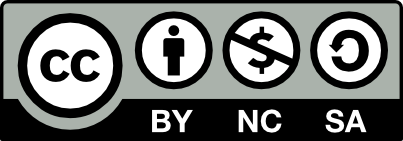 Práctica 4 © 2024 por José Parera licenciada bajo [CC BY-NC-SA 4.0](https://creativecommons.org/licenses/by-nc-sa/4.0/?ref=chooser-v1)